### AAE333 Lab2 Matlab Code (Author: Tomoki Koike)

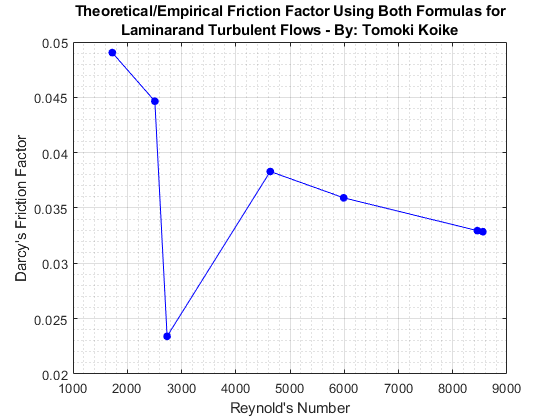

% Reading the excel files into matlab
file1 = readmatrix('data_partA.xlsx');
file2 = readmatrix('data_partB.xlsx');

% Setting variables
rho = 997; % Density of water [kg/m^3]
myu = 0.0011373; % Viscosity of water at room temperature [Pa-s]
g = 9.80665; % Gravitational acceleration [m/s^2]

% Slicing the matrix from the excel files and assigning them to specified variables
h_diff = [(file1(:,5)-file1(:,6)); (file2(:,5)-file2(:,6))]; % Height h 
h_diff = rmmissing(h_diff); % Removing NaN values from matrix
vel = rmmissing([file1(:,10); file2(:,10)]); % Velocity of the flow
len = rmmissing([file1(:,7); file2(:,7)]); % Length of pipe
d = rmmissing([file1(:,3); file2(:,3)]); % Diameter of the pipe

% Calculating the Reynold's number
Re = rho * vel .* d / myu; 
% Calculating the theoretical/empirical friction factors 
% Only the Dam A in part A of the experiment created a fully developed
% laminar flow. Therefore, we will use a different equation to find the
% friction factor for that flow only.
f = 0.316 ./ Re.^(0.25); % Friction factor formula for translational or turbulent flow
f(1) = 64 / Re(1); % Replace the certain one with the friction factor for laminar flow
temp = [Re f]; % Concatenate the two to sort them out correspondingly using sortrow
temp = sortrows(temp,1);
Re_sort = temp(:,1);
f_sort = temp(:,2);

% Plot for now
figure(1)
plot(Re_sort, f_sort, '.-b', 'MarkerSize', 20)
xlabel('Reynold''s Number')
ylabel('Darcy''s Friction Factor')
title({'Theoretical/Empirical Friction Factor Using Both Formulas for', ['Laminar' ...
    'and Turbulent Flows - By: Tomoki Koike']})
grid on
grid minor
box on

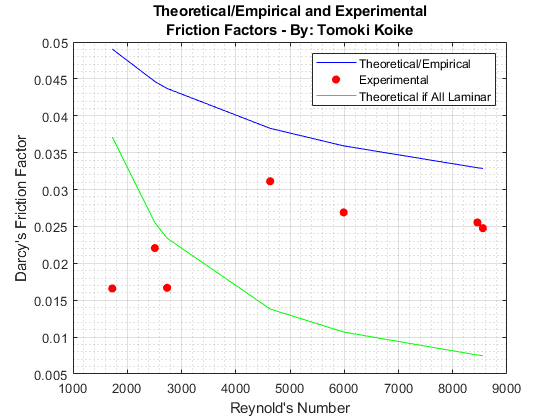


f_sort(3) = 0.316 / Re_sort(3)^(0.25); % Replace with the formula for the turbulent flow

% Calculating the experimental friction factor
comp1 = rho * g .* h_diff;
comp2 = rho .* vel.^2 / 2;
comp3 = len ./ d;
f_exp = comp1 ./ comp2 ./ comp3;
f_lam = 64 ./ Re_sort;

% Plot
figure(2)
plot(Re_sort, f_sort, '-b')
xlabel('Reynold''s Number')
ylabel('Darcy''s Friction Factor')
title({'Theoretical/Empirical and Experimental', ['Friction ' ...
    'Factors - By: Tomoki Koike']})
grid on 
grid minor
box on
hold on 
plot(Re, f_exp, '.r', 'MarkerSize',21)
plot(Re_sort, f_lam, '-g')
hold off
legend('Theoretical/Empirical','Experimental', 'Theoretical if All Laminar')

## Analysis

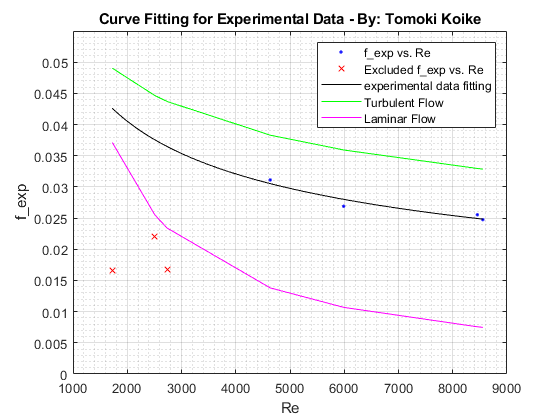

figure(3)
[result gof] = createFit(Re, f_exp);
hold on
plot(Re_sort, f_sort, '-g')
plot(Re_sort, f_lam, '-m')
hold off
title('Curve Fitting for Experimental Data - By: Tomoki Koike')
legend('f_exp vs. Re', 'Excluded f_exp vs. Re', ['experimental' ...
    ' data fitting'], 'Turbulent Flow', ['Laminar ' ...
    'Flow'],'Location', 'NorthEast', 'Interpreter', 'none' );
ylim([0 0.055])


% Calculating the Frechet Distance to measure dissimilarity of the
% functions 
Re_test = 1500:9000;
f_tur = 0.316 ./ Re_test.^(0.25);
f_fit = 0.525 ./ Re_test.^(0.337);
f_lmn = 64 ./ Re_test;
[cm1, cSq1] = DiscreteFrechetDist(f_tur, f_fit);
[cm2, cSq2] = DiscreteFrechetDist(f_lmn, f_fit);